# Horizontal displacement & rotation code

## Import video data (from camera 1) 

%%% Imports video 1
Dataset_Ruler = 'Ruler Case';
Camera_Ruler = 'cam1_5';
Camera_Format = 'mp4';

vidData_Ruler = importCamVideo(Dataset_Ruler,Camera_Ruler,Camera_Format);


## Camera 1

### Shows uncropped and cropped frame in colour

%%% Shows uncropped and cropped frame in colour
frame_Ruler = 101

frame_Ruler = 101

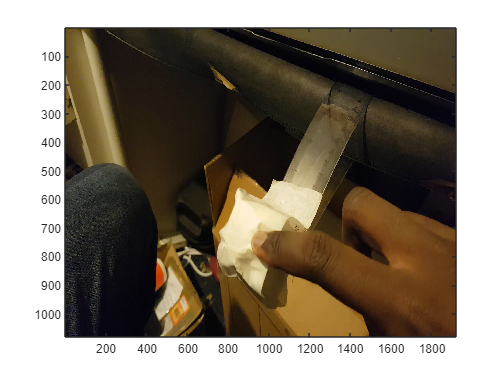


vidImage_Ruler = image(vidData_Ruler.vidFrames(:,:,:,frame_Ruler));

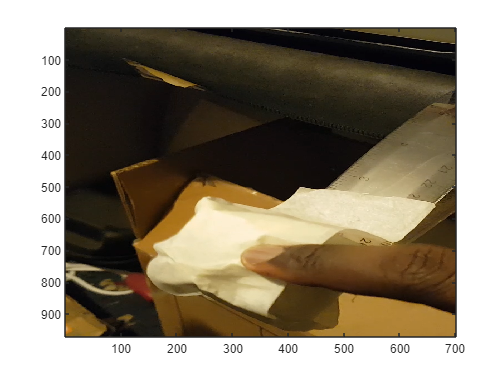

width_Ruler = 600:1300;
height_Ruler = 30:1000;
croppedFrame_Ruler = vidData_Ruler.vidFrames(height_Ruler,width_Ruler,:,frame_Ruler);
croppedFrame1_Ruler = vidData_Ruler.vidFrames(height_Ruler,width_Ruler,:,1);
vidImageCropped_Ruler = image(croppedFrame_Ruler);

### Shows frame of grayscale image

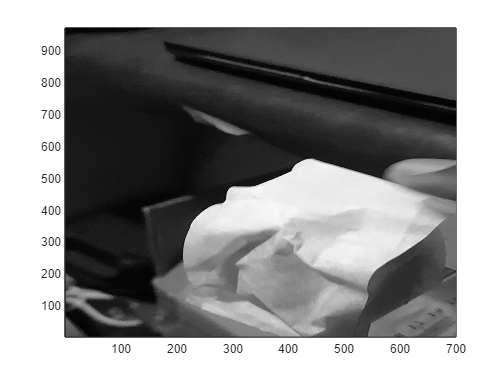

%%% Shows a frame from any camera as a grayscale colourmap (to locate
%%% locations of particular points

%%% Modified from: Data-Driven Modeling & Scientific Computation: 
%%% Methods for Complex Systems & Big Data 
%%% by J. NATHAN KUTZ


a_Ruler = flipud( double( rgb2gray( vidData_Ruler.vidFrames(height_Ruler,width_Ruler,:,1) )));
% a_Ruler = flipud( double( rgb2gray( vidData_Ruler_2.vidFrames(height_Ruler_2,width_Ruler_2,:,1) )));
% a_Ruler = flipud( double( rgb2gray( vidData_Ruler_3.vidFrames(height_Ruler_3,width_Ruler_3,:,1) )));
% a_Ruler = flipud( double( rgb2gray( vidData_Ruler_4.vidFrames(height_Ruler_4,width_Ruler_4,:,1) )));

% x = 1:640;
% y = 1:480;
% [X,Y]=meshgrid(x,y);
% pcolor(X,Y,a)
pcolor(a_Ruler)
shading interp
colormap("gray")

% set(gca,'Xtick',[],'Ytick',[],'Ztick',[])


### Finds and shows cap pixels (using both methods)

%%% Finds and shows cap pixels
x_Ruler = 389;
y_Ruler = 419;


r_Ruler = croppedFrame1_Ruler(end-y_Ruler,x_Ruler,1)

r_Ruler = uint8
238

g_Ruler = croppedFrame1_Ruler(end-y_Ruler,x_Ruler,2)

g_Ruler = uint8
224

b_Ruler = croppedFrame1_Ruler(end-y_Ruler,x_Ruler,3)

b_Ruler = uint8
177

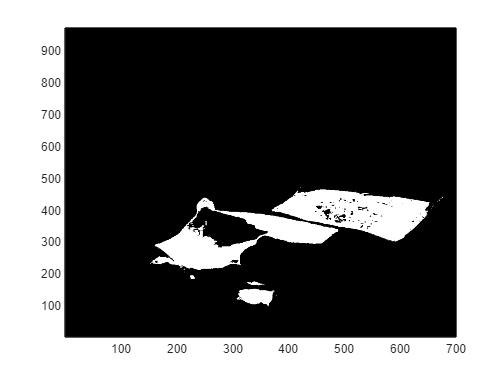


d_Ruler = 20;
cap_Pixels_Ruler = ((croppedFrame_Ruler(:,:,1) >= r_Ruler - d_Ruler) & (croppedFrame_Ruler(:,:,1) <= r_Ruler + d_Ruler)) ...
            &((croppedFrame_Ruler(:,:,2) >= g_Ruler - d_Ruler) & (croppedFrame_Ruler(:,:,2) <= g_Ruler + d_Ruler)) ...
            &((croppedFrame_Ruler(:,:,3) >= b_Ruler - d_Ruler) & (croppedFrame_Ruler(:,:,3) <= b_Ruler + d_Ruler));

pcolor(flipud(cap_Pixels_Ruler))
shading interp
colormap("gray")

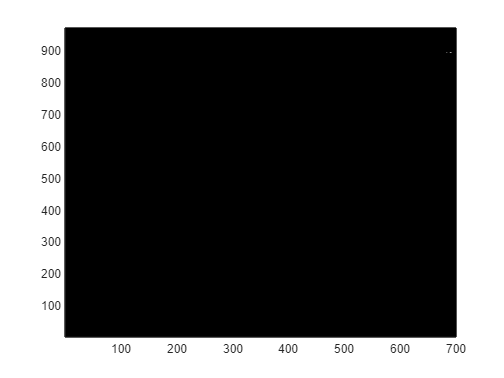


cap_Pixels_Ruler_2 = getCapPixelsBright(croppedFrame_Ruler,d_Ruler);

pcolor(flipud(cap_Pixels_Ruler_2))
shading interp
colormap("gray")

### Finds x and y coordinate of average of cap pixels

%%% Finds x and y coordinate of average of cap pixels
bounds_Ruler = Boundaries(cap_Pixels_Ruler)

bounds_Ruler = 469

[top_Ruler,bottom_Ruler,left_Ruler,right_Ruler] = Boundaries(cap_Pixels_Ruler)

top_Ruler = 469

bottom_Ruler = 96

left_Ruler = 153

right_Ruler = 679


[x_Ruler,y_Ruler] = centre(top_Ruler,bottom_Ruler,left_Ruler,right_Ruler)

x_Ruler = 416

y_Ruler = 282.5000

[x_avg_Ruler,y_avg_Ruler] = centre_avg(cap_Pixels_Ruler)

x_avg_Ruler = 413.6365

y_avg_Ruler = 338.1340

### Finds position of cap and stores it into a vector

%%% Finds position of cap and stores it into a vector
numFrames_Ruler = size(vidData_Ruler.vidFrames(1,1,1,:),4);
% width_Ruler = 600:1300;
% height_Ruler = 30:1000;
croppedFrame1_Ruler = vidData_Ruler.vidFrames(height_Ruler,width_Ruler,:,1);

x_Ruler = 389;
y_Ruler = 419;
d_Ruler = 20;

X_0_Ruler = zeros(1,numFrames_Ruler);
Y_0_Ruler = zeros(1,numFrames_Ruler);

for i = 1:numFrames_Ruler
    croppedFrame_Ruler = vidData_Ruler.vidFrames(height_Ruler,width_Ruler,:,i);
    cap_Pixels_Ruler = getCapPixels(croppedFrame1_Ruler,croppedFrame_Ruler,x_Ruler,y_Ruler,d_Ruler);
    
    [x_avg_Ruler,y_avg_Ruler] = centre_avg(cap_Pixels_Ruler);
    X_0_Ruler(i) = x_avg_Ruler;
    Y_0_Ruler(i) = y_avg_Ruler;
end

X_0_Ruler

X_0_Ruler =   453.5302  442.8314  432.8304  427.5202  425.4737  428.0856  432.7553  432.7401  431.4500  434.1066  433.7077  430.3314  424.0544  416.8616  411.0572  408.5109  407.7635  406.6945  407.4480  407.3843  406.6330  410.8644  412.7990  411.2362  415.0215  417.8170  417.6493  419.7807  426.2468  427.5251  435.1344  437.9429  442.9743  447.0604  451.9079  458.6132  461.4311  462.9337  463.5538  463.9071  461.6110  459.2067  459.0170  459.4131  455.8934  455.0824  457.9993  458.0902  455.6976  455.3161


Y_0_Ruler

Y_0_Ruler =   394.0346  389.4666  394.7596  369.0817  356.2947  364.6066  374.2648  371.2136  372.1614  380.8129  381.7695  368.9964  356.7796  338.9236  318.9778  310.7254  306.1749  294.6162  286.0529  282.1697  269.5752  252.4638  247.9525  247.6417  240.2072  235.2666  235.4096  233.0471  226.5708  224.4116  217.1822  220.0211  233.9779  248.1261  252.6162  253.9546  260.4066  272.3792  277.3448  281.5653  288.6270  293.3167  293.8538  293.8373  291.9231  287.0895  281.2999  282.2102  282.0206  280.2618


### Plots X and Y for camera 1

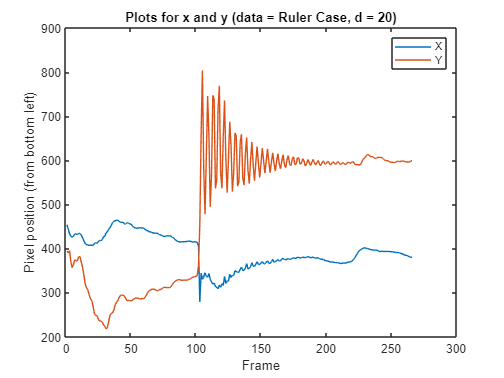

%%% Plots X and Y
plot(X_0_Ruler)
title('Plots for x and y (data = Ruler Case, d = 20)')
xlabel('Frame')
ylabel('Pixel position (from bottom left)')
hold on
plot(Y_0_Ruler)
legend('X','Y')
hold off

### Finds and plots X and Y for camera 1 for any d (with function that uses initial position)

%%% Finds and plots X and Y for any d (with function)
% width_Ruler = 600:1300;
% height_Ruler = 30:1000;

% x_Ruler = 389;
% y_Ruler = 419;
x_Ruler = 389;
y_Ruler = 419;
d1_Ruler = 50;

[X_11_Ruler,Y_11_Ruler] = getXY(vidData_Ruler.vidFrames,width_Ruler,height_Ruler,x_Ruler,y_Ruler,d1_Ruler)

X_11_Ruler =   460.5002  448.4575  433.4010  430.3132  428.3160  429.2483  432.3940  431.9836  429.1748  430.7023  430.7240  427.1293  421.5908  417.7035  414.7545  412.8155  412.2851  412.0559  412.5886  411.8534  412.4411  415.1879  414.9027  411.6713  411.9606  412.0126  409.8999  408.4063  409.2422  407.8584  408.2017  411.2915  413.3514  410.1942  411.5353  414.9036  417.1524  416.6845  416.1822  416.1422  413.9387  411.0130  410.9539  411.3740  411.8508  416.7964  420.2000  418.5072  416.9799  416.9724


Y_11_Ruler =   367.0664  359.9145  363.0362  351.1665  333.0621  340.6710  345.6464  341.3037  341.8280  343.6617  344.8451  336.0030  328.3463  318.2251  301.9510  293.0709  289.4721  278.6865  270.7779  266.5407  254.9986  238.1755  232.8805  233.6087  228.3311  224.7150  226.5182  227.0302  222.8844  221.9383  218.9370  221.1023  236.9599  249.7646  253.0301  252.8336  258.4856  269.4608  274.6528  278.2651  285.0102  289.6333  288.7614  286.3034  283.4312  275.3142  268.2325  268.3608  268.4241  266.4658


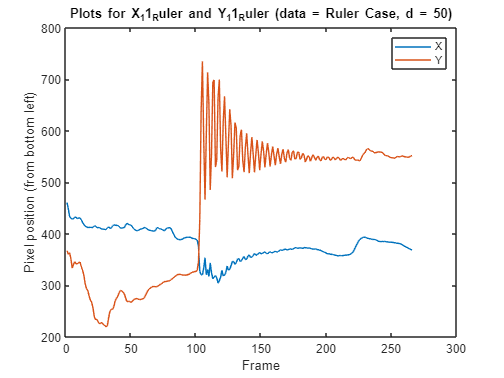

% X_11_Ruler = X_11_Ruler+width_Ruler(1);
% Y_11_Ruler = Y_11_Ruler+height_Ruler(1);

plotXY(X_11_Ruler,Y_11_Ruler,d1_Ruler,Dataset_Ruler)

### Finds and plots X and Y for camera 1 for any d (with function that uses brightness)

%%% Finds and plots X and Y for any d (with function)
% width_Ruler = 600:1300;
% height_Ruler = 30:1000;
d2_Ruler = 50;

[X_12_Ruler,Y_12_Ruler] = getXYBright(vidData_Ruler.vidFrames,width_Ruler,height_Ruler,d2_Ruler)

X_12_Ruler =   356.9333  360.5660  352.6757  363.7905  345.5563  362.9655  337.6507  355.6909  365.2387  374.8207  375.5463  378.4810  380.5905  379.2250  377.3864  372.0279  373.5013  371.6024  372.8773  369.4831  369.4977  377.0136  378.8456  376.1603  380.2659  385.3616  387.3276  391.5838  391.7295  391.1184  397.9776  398.8498  403.3947  410.4123  414.8596  419.0016  420.0245  422.0601  422.0353  420.1752  418.8012  419.2011  419.4978  419.1022  419.1904  425.3978  430.6207  428.7317  427.1015  427.3916


Y_12_Ruler =   391.8735  382.3864  385.1750  352.9305  354.7521  354.0476  370.7093  363.2233  365.2898  374.5938  373.4425  367.7966  364.0465  351.0603  337.8699  335.4526  329.9474  320.6883  316.7107  307.4298  299.2725  285.3324  286.6718  288.5056  280.3533  274.0303  273.4516  270.3989  270.1668  265.4470  254.2524  257.7444  272.0194  282.5967  285.9180  285.0335  289.6501  299.9880  306.0601  308.0482  314.5821  320.3107  320.9329  318.7733  316.2657  308.8952  302.1282  300.6847  300.9876  299.7657


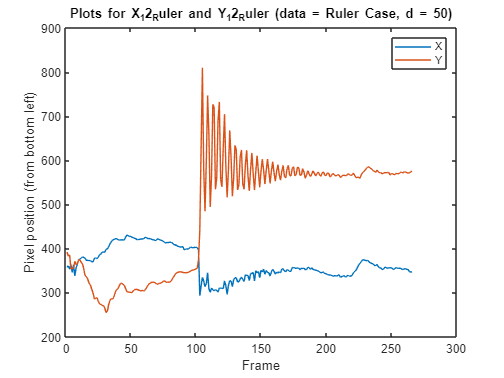


plotXY(X_12_Ruler,Y_12_Ruler,d2_Ruler,Dataset_Ruler)

## Camera 2

### Imports data

%%% Imports video 2
Dataset_Ruler_2 = 'Ruler Case';
Camera_Ruler_2 = 'cam2_5';
Camera_Format_2 = 'mp4';

vidData_Ruler_2 = importCamVideo(Dataset_Ruler_2,Camera_Ruler_2,Camera_Format_2);

### Shows uncropped and cropped frame in colour

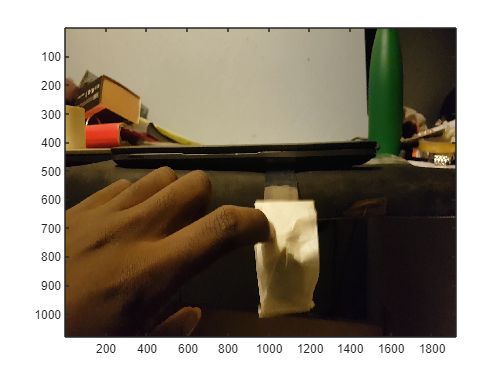

%%% Shows uncropped and cropped frame in colour for 2nd camera
frame_Ruler_2 = 108;

vidImage_Ruler_2 = image(vidData_Ruler_2.vidFrames(:,:,:,frame_Ruler_2));

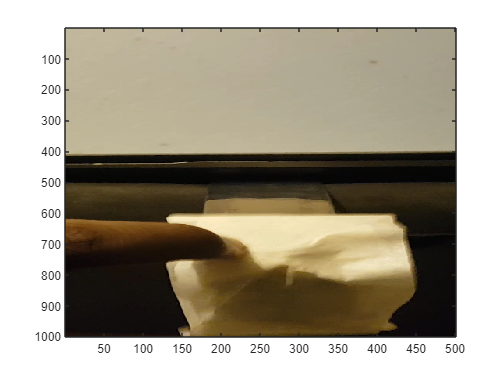

width_Ruler_2 = 800:1300;
height_Ruler_2 = 1:1000;
croppedFrame_Ruler_2 = vidData_Ruler_2.vidFrames(height_Ruler_2,width_Ruler_2,:,frame_Ruler_2);
vidImageCropped_Ruler_2 = image(croppedFrame_Ruler_2);

### Finds and plots X and Y for camera 2 (using initial position)

%%% Finds and plots X and Y for camera 2
% width_Ruler_2 = 800:1300;
% height_Ruler_2 = 1:1000;

x_Ruler_2 = 98;
y_Ruler_2 = 594;
d1_Ruler_2 = 50;

[X_21_Ruler,Y_21_Ruler] = getXY(vidData_Ruler_2.vidFrames,width_Ruler_2,height_Ruler_2,x_Ruler_2,y_Ruler_2,d1_Ruler_2)

X_21_Ruler =   178.0898  179.3518  182.4465  185.4042  184.7819  190.3329  191.8189  193.5877  196.8705  197.9890  199.3980  199.6430  200.2610  201.0021  201.3881  201.1366  202.8311  205.4930  206.6773  207.0947  207.5771  208.5647  209.9978  207.7366  206.9758  210.4578  212.0682  216.2260  217.7414  216.8086  217.8388  217.6268  216.9925  217.5198  218.1741  218.9236  219.8117  218.9569  218.5700  219.3176  219.2771  216.7846  214.9729  217.6809  220.4922  224.1318  229.6511  232.1774  233.8257  235.3312


Y_21_Ruler =   606.0776  613.9109  631.3219  645.1303  659.0280  648.8945  657.5791  655.8558  657.6725  649.2116  650.3966  650.9676  656.1897  658.6807  660.2965  664.4901  663.2500  648.0869  638.1285  628.5687  609.3411  601.6971  591.8762  572.1502  553.8675  535.7138  529.1945  522.1295  516.0048  501.0127  487.0869  475.9080  465.9832  457.0226  449.5687  438.9743  426.5787  425.6089  433.3533  433.7236  433.2584  434.5298  428.8537  418.3781  401.3778  386.5461  366.0550  358.7014  350.9760  343.6647


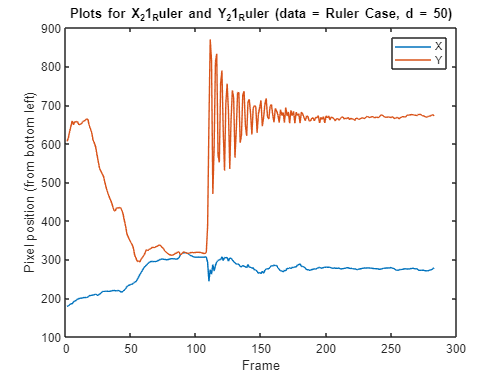


plotXY(X_21_Ruler,Y_21_Ruler,d1_Ruler_2,Dataset_Ruler)

### Finds and plots X and Y for camera 2 (using brightness)

%%% Finds and plots X and Y for camera 2
% width_Ruler_2 = 800:1300;
% height_Ruler_2 = 1:1000;
d2_Ruler_2 = 50;

[X_22_Ruler,Y_22_Ruler] = getXYBright(vidData_Ruler_2.vidFrames,width_Ruler_2,height_Ruler_2,d2_Ruler_2)

X_22_Ruler =   355.7013  353.3136  362.7922  370.5936  373.9139  382.3905  376.5990  373.2084  307.6225  299.4004  301.5937  299.3107  291.6101  287.2857  281.8862  278.5149  275.7723  271.9864  271.3503  270.2032  271.7858  278.2578  275.5290  276.8205  277.3787  272.0874  272.7092  268.0427  265.0728  270.2116  272.0546  272.3803  274.8382  278.0264  277.4179  273.2042  271.1319  269.6738  274.8712  283.1271  289.8658  311.7811  314.8974  309.8331  314.6981  311.0119  311.7325  314.0868  319.6464  322.1830


Y_22_Ruler =   742.3432  739.9211  738.8759  740.6820  740.4366  738.6126  737.8106  737.2758  757.0545  753.4071  751.5273  749.6816  747.2619  744.5370  742.3397  740.7697  738.8314  735.1500  730.7647  726.2413  721.6238  717.4730  716.7835  710.5089  706.1467  705.9976  708.6411  706.2016  702.2621  699.6032  695.6396  695.5676  690.6338  690.9135  682.8321  680.2400  676.9409  670.5313  669.2259  665.8168  660.3973  656.6056  660.2692  649.2276  647.1247  638.5938  629.8677  629.5703  625.4663  626.3553


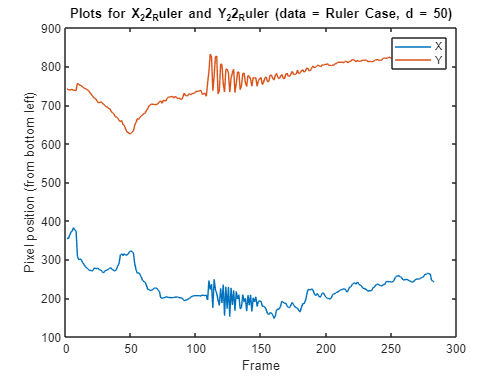


plotXY(X_22_Ruler,Y_22_Ruler,d2_Ruler_2,Dataset_Ruler)

## Camera 3

### Import data

%%% Imports video 3
Dataset_Ruler_3 = 'Ruler Case';
Camera_Ruler_3 = 'cam3_5';
Camera_Format_3 = 'mp4';

vidData_Ruler_3 = importCamVideo(Dataset_Ruler_3,Camera_Ruler_3,Camera_Format_3);


### Shows uncropped and cropped frame in colour

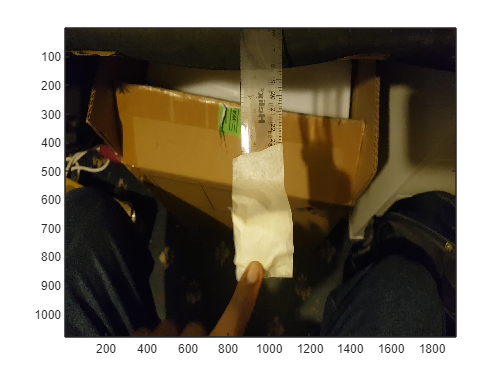

%%% Shows uncropped and cropped frame in colour for 3rd camera
frame_Ruler_3 = 66;

vidImage_Ruler_3 = image(vidData_Ruler_3.vidFrames(:,:,:,frame_Ruler_3));

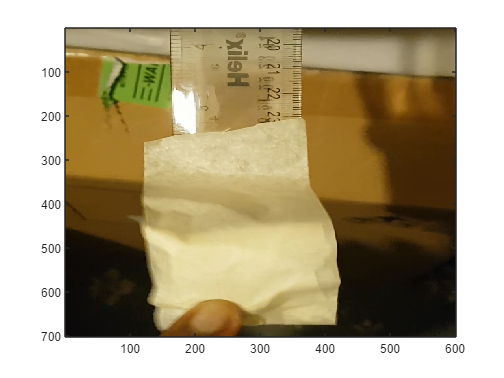

width_Ruler_3 = 700:1300;
height_Ruler_3 = 200:900;
croppedFrame_Ruler_3 = vidData_Ruler_3.vidFrames(height_Ruler_3,width_Ruler_3,:,frame_Ruler_3);
vidImageCropped_Ruler_3 = image(croppedFrame_Ruler_3);

### Finds and plots X and Y for camera 3 (using initial position)

%%% Finds and plots X and Y for camera 3
% width_Ruler_3 = 700:1300;
% height_Ruler_3 = 200:900;

x_Ruler_3 = 163;
y_Ruler_3 = 337;
d1_Ruler_3 = 50;

[X_31_Ruler,Y_31_Ruler] = getXY(vidData_Ruler_3.vidFrames,width_Ruler_3,height_Ruler_3,x_Ruler_3,y_Ruler_3,d1_Ruler_3)

X_31_Ruler =   209.2998  208.7946  209.7670  210.8003  211.9672  213.4855  214.7064  215.8388  215.9298  217.5952  220.6927  223.0939  225.1557  227.4811  231.4228  235.3259  237.4964  239.5062  241.8892  243.1361  244.3072  245.0525  244.6898  245.0475  245.4265  244.6882  244.4795  245.3822  245.7778  246.6194  246.1509  247.5746  247.2719  247.0413  246.6693  245.6078  244.2764  243.8633  244.0434  244.7062  245.9678  246.9869  248.9690  251.1636  252.9988  254.8313  256.9796  258.5262  259.4173  260.1482


Y_31_Ruler =   374.8519  372.4586  368.5795  367.9620  365.4765  358.5234  352.9209  348.6102  344.8075  339.6697  333.8778  328.1302  322.5970  317.1599  312.1217  307.0485  301.8024  296.9143  290.3244  283.8547  279.7961  277.0273  275.9679  275.8494  278.0797  280.6065  282.5311  284.1498  285.0197  288.3773  290.3549  288.7363  289.2697  288.9153  288.4570  288.0694  289.8896  289.8354  289.6655  288.8997  288.7188  286.6173  284.9766  283.9368  283.1485  283.3225  284.2254  285.4285  287.4101  288.0696


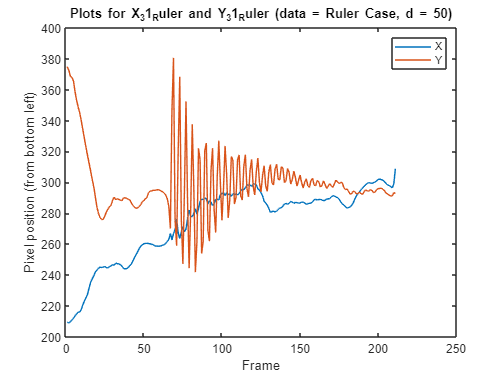


plotXY(X_31_Ruler,Y_31_Ruler,d1_Ruler_3,Dataset_Ruler)

### Finds and plots X and Y for camera 3 (using brightness)

%%% Finds and plots X and Y for camera 3
% width_Ruler_3 = 700:1300;
% height_Ruler_3 = 200:900;
d2_Ruler_3 = 20;

[X_32_Ruler,Y_32_Ruler] = getXYBright(vidData_Ruler_3.vidFrames,width_Ruler_3,height_Ruler_3,d2_Ruler_3)

X_32_Ruler =        NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN  159.1221  162.3944  172.5741  174.6654  174.5169  171.1776  168.9636  168.4050  166.7766  166.5737  173.1963  177.3701  174.5903  172.5721  166.3533  167.0142  166.5273  165.8018  165.8271  172.4838  172.0564  177.0164  179.2496  180.6671  183.5753  184.9505  186.5808


Y_32_Ruler =        NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN  458.5446  460.3639  466.7328  472.8096  476.6998  484.7403  499.1324  513.3171  523.3340  539.0179  552.4932  557.3506  560.2847  563.2605  564.9756  565.8940  566.0902  563.9226  563.2198  561.3962  558.0312  556.7770  556.2670  554.0360  554.2163  555.0790  554.1489


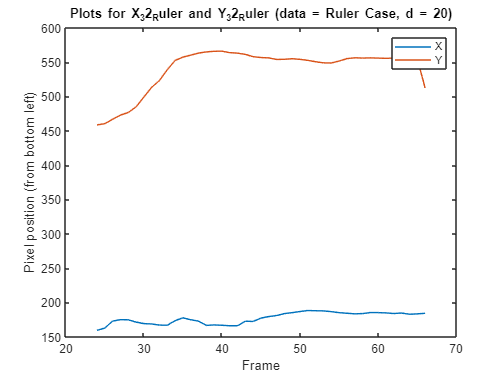


plotXY(X_32_Ruler,Y_32_Ruler,d2_Ruler_3,Dataset_Ruler)

## Camera 4

### Import data

%%% Imports video 4
Dataset_Ruler_4 = 'Ruler Case';
Camera_Ruler_4 = 'cam4_5';
Camera_Format_4 = 'mp4';

vidData_Ruler_4 = importCamVideo(Dataset_Ruler_4,Camera_Ruler_4,Camera_Format_4);


### Shows uncropped and cropped frame in colour

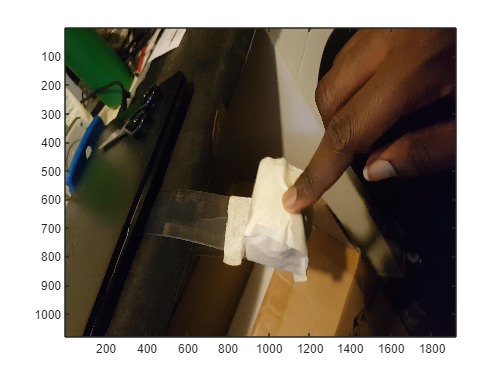

%%% Shows uncropped and cropped frame in colour for 4th camera
frame_Ruler_4 = 102;

vidImage_Ruler_4 = image(vidData_Ruler_4.vidFrames(:,:,:,frame_Ruler_4));

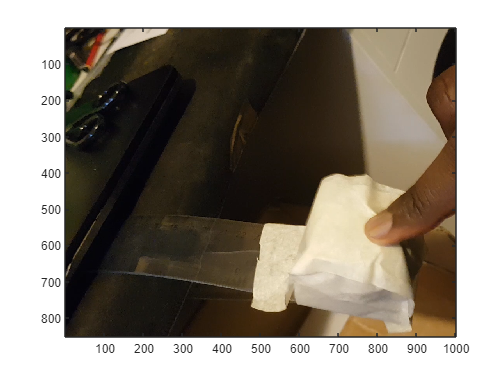

width_Ruler_4 = 300:1300;
height_Ruler_4 = 50:900;
croppedFrame_Ruler_4 = vidData_Ruler_4.vidFrames(height_Ruler_4,width_Ruler_4,:,frame_Ruler_4);
vidImageCropped_4 = image(croppedFrame_Ruler_4);

### Finds and plots X and Y for camera 4 (using initial position)

%%% Finds and plots X and Y for camera 4
% width_Ruler_4 = 300:1300;
% height_Ruler_4 = 50:900;

x_Ruler_4 = 353;
y_Ruler_4 = 390;
d1_Ruler_4 = 50;

[X_41_Ruler,Y_41_Ruler] = getXY(vidData_Ruler_4.vidFrames,width_Ruler_4,height_Ruler_4,x_Ruler_4,y_Ruler_4,d1_Ruler_4)

X_41_Ruler =   405.0255  405.8593  408.5695  411.1186  413.8608  415.9241  415.3750  413.6379  412.5211  410.6878  407.7332  405.0635  401.2017  397.7935  396.1525  396.7558  399.3560  401.3305  411.9629  426.1085  438.4815  454.3785  461.2843  463.1152  468.5207  474.9511  478.1966  483.9441  494.1678  504.8693  511.9503  519.9212  529.6942  534.1829  535.6159  545.5915  554.8982  554.2393  556.4716  568.0372  573.4266  571.9023  579.9666  594.9490  594.4824  582.7659  594.3360  604.0779  603.1072  604.6877


Y_41_Ruler =   415.6074  416.7694  418.8873  421.2984  423.1276  424.9317  426.3526  428.0695  429.2592  430.1356  429.5965  426.8456  421.4647  414.3683  407.2082  401.7734  397.5541  398.8595  397.7219  394.9032  391.1872  384.7197  382.4201  380.3512  374.6295  369.4384  366.6560  364.1236  359.2345  355.1513  352.7940  347.8088  342.8341  340.9211  338.0584  328.3722  323.2287  323.5429  321.0514  312.1664  310.9764  314.0326  306.7217  294.3370  295.5565  305.7308  297.1962  289.0596  290.1682  287.1624


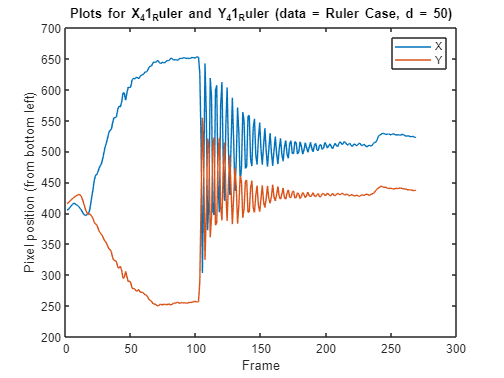


plotXY(X_41_Ruler,Y_41_Ruler,d1_Ruler_4,Dataset_Ruler)

### Finds and plots X and Y for camera 4 (using brightness)

%%% Finds and plots X and Y for camera 4
% width_Ruler_4 = 300:1300;
% height_Ruler_4 = 50:900;
d2_Ruler_4 = 20;

[X_42_Ruler,Y_42_Ruler] = getXYBright(vidData_Ruler_4.vidFrames,width_Ruler_4,height_Ruler_4,d2_Ruler_4)

X_42_Ruler =   785.8857  792.2753  793.4250  806.9223  812.0304  810.3977  811.5918  812.3663  809.4526  803.3367  797.2709  791.4479  789.8103  777.6478  770.8238  764.9054  756.1985  759.9554  760.3633  760.1540  756.8967  752.9322  752.3312  750.8924  740.8378  744.7912  747.9039  752.3454  745.2687  744.6077  720.9758  705.0027  676.4488  646.2548  621.9306  544.8595  466.1133  415.8902  381.7102  313.4947  312.4131  334.1008  357.1020  269.2110  261.9779  347.8071  311.0965  264.6871  282.6501  295.4720


Y_42_Ruler =   587.6822  589.8622  589.3819  584.6036  579.5760  582.5136  582.7682  584.0460  586.4531  590.3729  593.4512  596.2944  597.3415  599.9406  601.6141  603.1522  609.7890  611.9213  606.0474  605.1566  603.8447  591.7655  594.3977  592.9991  589.6296  593.8311  588.4692  590.2692  579.4591  576.4912  578.3508  567.0921  558.7386  559.7962  554.8464  520.9573  526.5498  533.5265  509.6534  488.1285  457.0816  439.9927  430.5042  509.6838  539.6803  468.8937  477.3130  509.3592  493.9842  495.0072


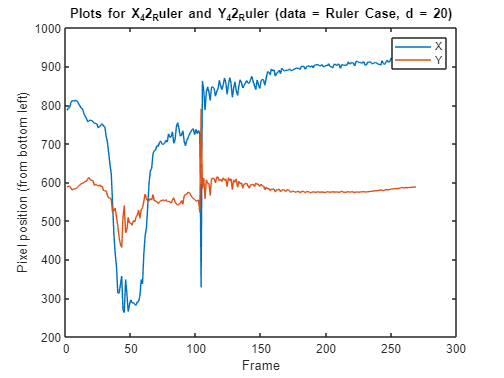


plotXY(X_42_Ruler,Y_42_Ruler,d2_Ruler_4,Dataset_Ruler)

## PCA

### Merge cameras' X and Y data

%%% The data is cropped to remove 'setting' before oscillations:
%%% Camera 1: 101 (frames)
%%% Camera 2: 108
%%% Camera 3: 66
%%% Camera 4: 102

f = [101, 108, 66, 102];
f_max = max(f)

f_max = 108


% Finds length by finding the minimum of the distances between the maximum
% frame and the end of each dataset
sz_Ruler = min( [size(X_11_Ruler(f_max:end),2), ...
                 size(X_21_Ruler(f_max:end),2), ...
                 size(X_31_Ruler(f_max:end),2), ...
                 size(X_41_Ruler(f_max:end),2)] )

sz_Ruler = 104


X_Ruler = cat( 1,X_11_Ruler(f(1):f(1) + sz_Ruler), ...
                 Y_11_Ruler(f(1):f(1) + sz_Ruler), ...
                 X_21_Ruler(f(2):f(2) + sz_Ruler), ...
                 Y_21_Ruler(f(2):f(2) + sz_Ruler), ...
                 X_31_Ruler(f(3):f(3) + sz_Ruler), ...
                 Y_31_Ruler(f(3):f(3) + sz_Ruler), ...
                 X_41_Ruler(f(4):f(4) + sz_Ruler), ...
                 Y_41_Ruler(f(4):f(4) + sz_Ruler) )

X_Ruler =   387.7474  375.6066  326.2364  320.0056  320.0606  332.9620  353.2961  320.1302  330.5187  316.7243  343.1388  323.7893  312.5076  315.5718  318.4741  314.4275  303.9464  308.8067  315.5645  329.1168  317.6942  319.6936  324.4498  337.4900  329.1489  330.8663  338.0259  345.8303  346.0030  340.3675  343.8747  350.5830  351.7112  345.7360  347.9222  352.3470  355.6669  349.4216  350.8923  356.5377  358.9449  353.6586  354.8779  357.4337  361.8227  358.0136  359.3264  361.2664  363.5424  360.6539
  328.2153  346.1264  428.2233  635.8917  734.9939  583.8237  466.3147  594.1247  713.4600  652.2759  484.9860  555.4549  695.1861  699.0165  529.3168  543.3636  663.7956  699.6436  565.1530  520.6540  618.5315  667.1080  589.8731  509.5535  577.0761  641.8393  609.1875  507.6871  554.1142  616.0836  605.4345  523.4171  531.8008  591.3109  602.2189  541.8614  519.5872  568.3423  595.1856  553.0768  517.6453  558.3889  587.6352  554.1040  519.2565  553.6466  582.4353  557.2655  523.243

### Do PCA on the data matrix (using SVD decomposition)

[~,Y_Ruler,lambda_Ruler] = pca(X_Ruler.')

Y_Ruler =  -466.8875  -83.4030  -38.9440   27.9654  -20.1468   25.2697   -1.6645    9.0432
 -389.4778  -80.6811  -25.2640   12.2381  -10.3181   30.0260  -19.1061   -7.0932
  -59.8933 -114.3449    0.4237  -69.5586  -25.8122   -0.6272   -8.7148  -15.5214
  321.9753  -77.8242  -37.8384    0.0285  -37.6490   -2.7775    4.0591    9.2300
  213.0629  116.7335    4.2567    1.0970  -29.0574    1.7921   -6.5721  -15.6448
 -233.0791  116.8481  -44.0805   15.8763  -26.2862  -18.4504    1.2862    5.3992
 -120.5094  -52.9191   -4.5248  -31.6609   -6.5931   -4.8948   13.1931  -11.4916
  218.9467  -68.8767  -33.7442  -19.1265  -23.8687    4.6026   13.4617    8.4559
  241.5701   81.1726   -6.9163   11.4504    0.0338   22.5696    3.6310  -15.1312
 -112.9910  160.2345  -34.2179    0.6930  -15.9510   -2.2137    6.7773    1.8113


lambda_Ruler = 	1.0e+03 *

    9.9721
    2.7763
    0.5178
    0.1660
    0.0761
    0.0551
    0.0370
    0.0327


Y_Ruler = Y_Ruler.'

Y_Ruler =  -466.8875 -389.4778  -59.8933  321.9753  213.0629 -233.0791 -120.5094  218.9467  241.5701 -112.9910 -159.7012  145.5274  224.7358  -35.3972 -169.8620   76.7203  188.0146   25.9483 -155.6822   13.5389  148.2026   59.8231 -122.4268  -29.9859  116.2565   77.8597  -83.0900  -55.7784   90.8495   84.5751  -45.5145  -62.5364   59.3063   70.1024  -18.4592  -64.6901   28.9176   50.8513   -1.4201  -64.4220    5.9686   43.2337   18.8853  -49.8299   -7.4570   42.6845   30.4034  -29.1421  -15.7075   39.4787
  -83.4030  -80.6811 -114.3449  -77.8242  116.7335  116.8481  -52.9191  -68.8767   81.1726  160.2345  -12.0047  -77.4084   52.1740  185.4750   42.1820  -56.7748   27.9908  170.9186   79.4644  -53.5471   -7.0207  121.7605   92.9110  -49.0076  -37.5474   78.7602   98.8584  -37.1858  -50.6006   39.9611   85.7183  -16.3631  -62.3345    6.9103   74.5348    9.8890  -60.0840  -13.9655   62.8926   25.5002  -52.1159  -25.2102   42.8450   23.1389  -45.1415  -27.9426   28.3716   23.0108  -35.110

### Plot PCA components 

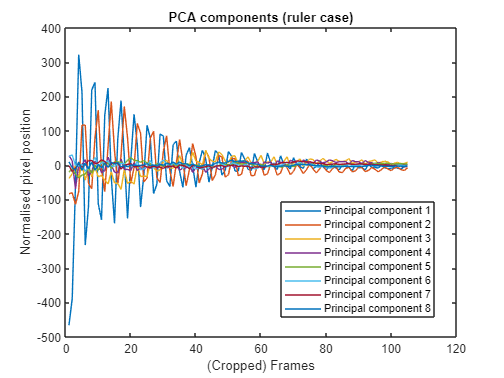

plot(Y_Ruler(1,:))
title('PCA components (ruler case)')
xlabel('(Cropped) Frames')
ylabel('Normalised pixel position')

hold on
plot(Y_Ruler(2,:))
plot(Y_Ruler(3,:))
plot(Y_Ruler(4,:))
plot(Y_Ruler(5,:))
plot(Y_Ruler(6,:))
plot(Y_Ruler(7,:))
plot(Y_Ruler(8,:))
legend('Principal component 1', ...
       'Principal component 2', ...
       'Principal component 3', ...
       'Principal component 4', ...
       'Principal component 5', ...
       'Principal component 6', ...
       'Principal component 7', ...
       'Principal component 8','Location','best')
hold off

### Plots PCA eigenvalues

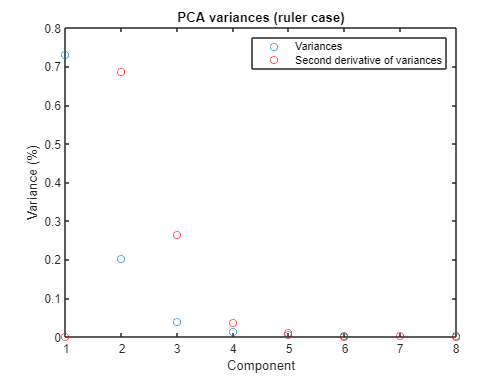

plot(lambda_Ruler/sum(lambda_Ruler), 'o')
title('PCA variances (ruler case)')
xlabel('Component')
ylabel('Variance (%)')

ddlambda_Ruler = zeros(size(lambda_Ruler));
for i = 1:length(lambda_Ruler)
    if i == 1
        ddlambda_Ruler(i) = 0;
    elseif i == length(lambda_Ruler)
        ddlambda_Ruler(i) = 0;
    else
        ddlambda_Ruler(i) = (lambda_Ruler(i+1) - 2*lambda_Ruler(i) + lambda_Ruler(i-1));
    end
end

hold on
plot(ddlambda_Ruler/sum(abs(ddlambda_Ruler)), 'ro')
legend('Variances','Second derivative of variances')
hold off

## Analysis

### Gets fast fourier transforms of largest principal components 

%%% Modified from fft documentation

Fs_Ruler = 1;            % Sampling frequency                    
T_Ruler = 1/Fs_Ruler;             % Sampling period       
L_Ruler = sz_Ruler;             % Length of signal
t_Ruler = (0:L_Ruler-1)*T_Ruler;        % Time vector

f_1_Ruler = fft(Y_Ruler(1,:))

f_1_Ruler = 	1.0e+03 *

  -0.0000 + 0.0000i  -0.5055 - 0.5716i  -0.5848 - 0.5632i  -0.7722 - 0.2561i  -0.7768 - 0.2167i  -0.8857 - 0.1941i  -0.8312 - 0.0320i  -0.7533 - 0.0690i  -0.8215 - 0.0424i  -0.7962 - 0.0190i  -0.7886 - 0.0010i  -0.8134 + 0.0242i  -0.8279 + 0.0354i  -0.8629 + 0.0387i  -0.8661 + 0.0464i  -0.9065 + 0.0677i  -0.9420 + 0.0745i  -0.9929 + 0.1385i  -1.0182 + 0.1622i  -1.0836 + 0.1768i  -1.1810 + 0.2837i  -1.2786 + 0.3363i  -1.5124 + 0.5374i  -1.7873 + 0.8547i  -2.0713 + 2.1269i   0.1193 + 3.6939i   2.0761 + 1.0324i   0.8132 + 0.4987i   0.3339 - 0.0114i   0.2370 + 0.1022i   0.1356 - 0.0307i  -0.0410 + 0.0440i  -0.0764 + 0.0418i  -0.0840 + 0.0353i  -0.1295 + 0.0352i  -0.1689 + 0.0296i  -0.1783 + 0.0170i  -0.2020 + 0.0124i  -0.2322 - 0.0007i  -0.2510 + 0.0092i  -0.2651 + 0.0168i  -0.2802 + 0.0281i  -0.3014 + 0.0251i  -0.2862 + 0.0366i  -0.3047 + 0.0627i  -0.3079 + 0.0588i  -0.3351 + 0.0742i  -0.2989 + 0.1286i  -0.2593 + 0.1517i  -0.1475 + 0.2041i


f_2_Ruler = 	1.0e+03 *

  -0.0000 + 0.0000i   0.2588 - 1.1041i  -0.4973 - 0.6021i  -0.6030 - 0.2126i  -0.4451 + 0.1205i  -0.3251 + 0.1171i  -0.2273 + 0.0626i  -0.2553 + 0.0531i  -0.2484 + 0.0849i  -0.3082 + 0.0696i  -0.2949 + 0.1445i  -0.2538 + 0.1662i  -0.2056 + 0.1625i  -0.1936 + 0.1974i  -0.1746 + 0.1915i  -0.1640 + 0.2226i  -0.1427 + 0.2117i  -0.1390 + 0.2344i  -0.1261 + 0.2635i  -0.1011 + 0.2756i  -0.1109 + 0.3217i  -0.0511 + 0.4228i   0.0192 + 0.4906i   0.1370 + 0.7636i   1.1251 + 1.0118i   1.9552 - 0.8779i  -0.4978 - 1.5996i  -0.0224 - 0.2569i  -0.4054 - 0.0847i  -0.2595 - 0.0439i  -0.1659 - 0.0479i  -0.1818 - 0.0281i  -0.1320 + 0.0191i  -0.1037 - 0.0198i  -0.1364 - 0.0176i  -0.1262 + 0.0112i  -0.1150 + 0.0210i  -0.1078 + 0.0232i  -0.1088 + 0.0258i  -0.1112 + 0.0435i  -0.0869 + 0.0567i  -0.0734 + 0.0606i  -0.0650 + 0.0447i  -0.0630 + 0.0522i  -0.0559 + 0.0548i  -0.0431 + 0.0518i  -0.0488 + 0.0587i  -0.0199 + 0.0857i   0.0468 + 0.0710i   0.0898 - 0.0398i


### Plot absolute values of the FFT

#### PC1

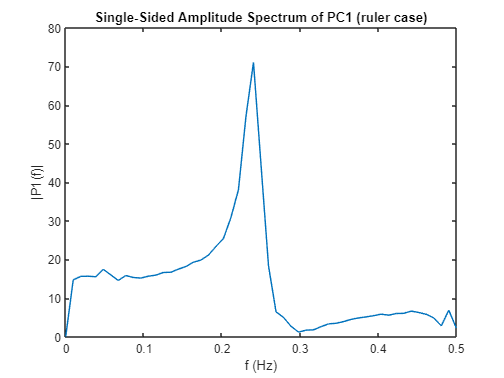

%%% Modified from fft documentation

P2_1_Ruler = abs(f_1_Ruler/L_Ruler);
P1_1_Ruler = P2_1_Ruler(1:L_Ruler/2+1);
P1_1_Ruler(2:end-1) = 2*P1_1_Ruler(2:end-1);

f1_Ruler = Fs_Ruler*(0:(L_Ruler/2))/L_Ruler;
plot(f1_Ruler,P1_1_Ruler) 
title('Single-Sided Amplitude Spectrum of PC1 (ruler case)')
xlabel('f (Hz)')
ylabel('|P1(f)|')


P1_1_max_Ruler = max(P1_1_Ruler)

P1_1_max_Ruler = 71.0739

f1_max_Ruler = 0.2404

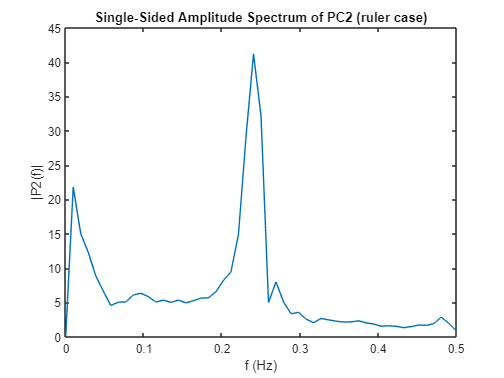

P1_2_max_Ruler = 41.2159

f2_max_Ruler = 0.2404

f1_max_Ruler = f1_Ruler(P1_1_Ruler == P1_1_max_Ruler)

### Use least square fitting to estimate damped sine waves for PCs (assuming damped harmonic motion)

#### PC1

%%% Minimise LSE: sum( abs( f(x_k)-y_k )^2 )
%%% Function: f(x) = A*e^(-zeta*omega_n*x)*sin(omega_d*x + phi)
%%% where omega_d = omega_n*sqrt(1-zeta^2)
xs_Ruler = 1:sz_Ruler + 1;
LSE_sin_1_Ruler = @(n) sum( abs( ...
    n(1).*exp(-n(2).*n(3).*xs_Ruler).*sin(n(3).*sqrt(1-n(2).^2).*xs_Ruler + n(4)) ...
    -Y_Ruler(1,:) ).^2 );
n0_1_Ruler = [P1_1_max_Ruler, 0.1, f1_max_Ruler*2*pi, 0*(pi/180)];
coef_1_Ruler = fminsearch(LSE_sin_1_Ruler,n0_1_Ruler)

coef_1_Ruler =   473.6034    0.0423    1.4666    1.9840


Error_1_Ruler = LSE_sin_1_Ruler(coef_1_Ruler)

Error_1_Ruler = 2.2772e+05

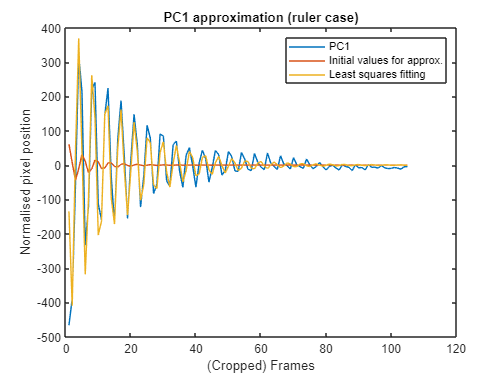


y_1_Ruler = coef_1_Ruler(1).*exp(-coef_1_Ruler(2).*coef_1_Ruler(3).*xs_Ruler).*sin(coef_1_Ruler(3).*sqrt(1-coef_1_Ruler(2).^2).*xs_Ruler + coef_1_Ruler(4));
y0_1_Ruler = n0_1_Ruler(1).*exp(-n0_1_Ruler(2).*n0_1_Ruler(3).*xs_Ruler).*sin(n0_1_Ruler(3).*sqrt(1-n0_1_Ruler(2).^2).*xs_Ruler + n0_1_Ruler(4));

plot(Y_Ruler(1,:))
title('PC1 approximation (ruler case)')
xlabel('(Cropped) Frames')
ylabel('Normalised pixel position')
hold on
plot(y0_1_Ruler)
plot(y_1_Ruler)
legend('PC1','Initial values for approx.', 'Least squares fitting')
hold off

## Various functions are here:

### Imports video

function vidData = importCamVideo(Dataset,Camera,Format)

Data_path = join( ['C:' ...
    '\Users' ...
    '\dakin' ...
    '\OneDrive - University College London' ... 
    '\Project Datasets' ...
    '\',Dataset, ... 
    '\',Camera, ...
    '.',Format] ); % Change to location of files

% The following is modified from 'Read Video Files' documentation
vidObj = VideoReader(Data_path);
vidData = struct('vidFrames', ...
    zeros(vidObj.Height,vidObj.Width,3,vidObj.NumFrames,'uint8'),'colormap',[]);

k = 1;
while k <= vidObj.NumFrames
    vidData.vidFrames(:,:,:,k) = readFrame(vidObj);
    k = k+1;
end


end



### Imports (MATLAB) data

function camData = importCamData(Dataset,Camera)

Data_path =join( ['C:' ...
    '\Users' ...
    '\dakin' ...
    '\OneDrive - University College London' ... 
    '\Project Datasets' ...
    '\',Dataset, ... 
    '\',Camera] ); % Change to location of files

camData = load( Data_path );

end



### Shows cropped and uncropped video frame

%%% Shows cropped and uncropped video frame
function [im_1,im_2] = showFrames(frameNum,vidFrame,width,height)

normFrame = vidFrame(:,:,:,frameNum);
im_1 = image(normFrame);

croppedFrame = vidFrame(height,width,:,frameNum);
im_2 = image(croppedFrame);

end



### Finds pixel that corresponds to cap

%%% Finds the pixels that correspond to the cap
function cap_Pixels = getCapPixels(croppedFrame1,croppedFrame,x,y,d)

if nargin == 4
    d = 10;
elseif nargin == 2
    x = 82;
    y = 198;
end


r = croppedFrame1(end-y,x,1);
g = croppedFrame1(end-y,x,2);
b = croppedFrame1(end-y,x,3);


cap_Pixels = ((croppedFrame(:,:,1) >= r - d) & (croppedFrame(:,:,1) <= r + d)) ...
            &((croppedFrame(:,:,2) >= g - d) & (croppedFrame(:,:,2) <= g + d)) ...
            &((croppedFrame(:,:,3) >= b - d) & (croppedFrame(:,:,3) <= b + d));
end



### Finds the pixels that correspond to the cap using brightness

%%% Finds the pixels that correspond to the cap
function cap_Pixels = getCapPixelsBright(croppedFrame,d)

if nargin == 1
    d = 10;
end

br = max( rgb2gray(croppedFrame) );

cap_Pixels = ((croppedFrame(:,:,1) >= br - d) & (croppedFrame(:,:,1) <= br + d)) ...
            &((croppedFrame(:,:,2) >= br - d) & (croppedFrame(:,:,2) <= br + d)) ...
            &((croppedFrame(:,:,3) >= br - d) & (croppedFrame(:,:,3) <= br + d));
end

### Finds the bounds for the cap pixels

%%% Finds the bounds for the cap pixels
function [top,bottom,left,right] = Boundaries(cap_Pixels)

top = 0;
bottom = 0;
left = 0;
right = 0;

sz_row = size(cap_Pixels,1);
for i = 1:sz_row
    findOne = size(find(cap_Pixels(i,:)));
    if findOne(2) ~= 0
        top = sz_row - i;
        break;
    end
end

for i = 1:sz_row
    findOne = size(find(cap_Pixels(end-i,:)));
    if findOne(2) ~= 0
        bottom = i;
        break;
    end
end

sz_col = size(cap_Pixels,2);
for i = 1:sz_col
    findOne = size(find(cap_Pixels(:,i)));
    if findOne(1) ~= 0
        left = i;
        break;
    end
end

for i = 1:sz_col
    findOne = size(find(cap_Pixels(:,end-i)));
    if findOne(1) ~= 0
        right = sz_col - i;
        break;
    end
end

end



### Finds centre from bounds

%%% Finds centre from bounds
function [x,y] = centre(top,bottom,left,right)

y = mean([top,bottom]);
x = mean([left,right]);

end



### Finds centre from averaging the number of pixels

%%% Finds centre from averaging the number of pixels
function [x,y] = centre_avg(cap_Pixels)
[sz_row,sz_col] = size(cap_Pixels);

x = 0;
x_num = 0;
for i = 1:sz_col
    x = x + sum(cap_Pixels(:,i))*i ;
    x_num = x_num + sum(cap_Pixels(:,i)) ;
end
x = x/x_num;

y = 0;
y_num = 0;
for i = 1:sz_row
    y = y + sum(cap_Pixels(i,:))*i ;
    y_num = y_num + sum(cap_Pixels(i,:)) ;
end
y = sz_row - y/y_num;

end



### Gets X and Y data from camera data

%%% Gets X and Y data from camera data
function [X,Y] = getXY(camData,width,height,x,y,d)

if nargin == 5
    d = 10;
elseif nargin == 3
    x = 82;
    y = 198;
elseif nargin == 1
    width = 250:450;
    height = 200:425;
end

numFrames = size(camData(1,1,1,:),4);
croppedFrame1 = camData(height,width,:,1);

X = zeros(1,numFrames);
Y = zeros(1,numFrames);

for i = 1:numFrames
    croppedFrame = camData(height,width,:,i);
    cap_Pixels = getCapPixels(croppedFrame1,croppedFrame,x,y,d);
    
    
    [x_avg,y_avg] = centre_avg(cap_Pixels);
    X(i) = x_avg;
    Y(i) = y_avg;
end

end



### Gets X and Y data from camera data using brightness

%%% Gets X and Y data from camera data
function [X,Y] = getXYBright(camData,width,height,d)

if nargin == 3
    d = 10;
elseif nargin == 1
    width = 250:450;
    height = 200:425;
end

numFrames = size(camData(1,1,1,:),4);

X = zeros(1,numFrames);
Y = zeros(1,numFrames);

for i = 1:numFrames
    croppedFrame = camData(height,width,:,i);
    cap_Pixels = getCapPixelsBright(croppedFrame,d);
    
    [x_avg,y_avg] = centre_avg(cap_Pixels);
    X(i) = x_avg;
    Y(i) = y_avg;
end

end



### Plots X and Y on the same graph

%%% Plots X and Y on the same graph
function plotXY(X,Y,d,Dataset)

plot(X)
if nargin == 4
    title_text = join(['Plots for ',inputname(1), ...
        ' and ',inputname(2), ...
        ' (data = ',Dataset,', d = ',num2str(d),')']);
else
    title_text = join(['Plots for ',inputname(1), ...
        ' and ',inputname(2), ...
        ' (d = ',num2str(d),')']);
end
title(title_text)
xlabel('Frame')
ylabel('Pixel position (from bottom left)')
hold on
plot(Y)
legend('X','Y')
hold off

end



